 clc, clear all, close all; warning('off','all');

# **Laboratorio - Análisis y simulación de robot industrial**

# Robótica

#### Laura Valentina Garzón

#### Hernán David Moreno 

#### Laura Camila Perdomo

#### Mitchell Elizabeth Rodríguez

## Parte 1: Robot y ruta.

La referencia del motor utilizado es Robot IRB 1600-X/1.45 del fabricante ABB.

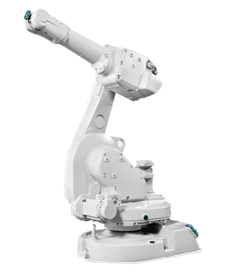

Este robot cuenta con varias versiones en las que varian sus dimensiones y capacidad de carga, en este caso se eligió la referencia IRB1600-X/1.45 y a partir de esto, con el siguiente plano se definieron las dimensiones de los eslabones.

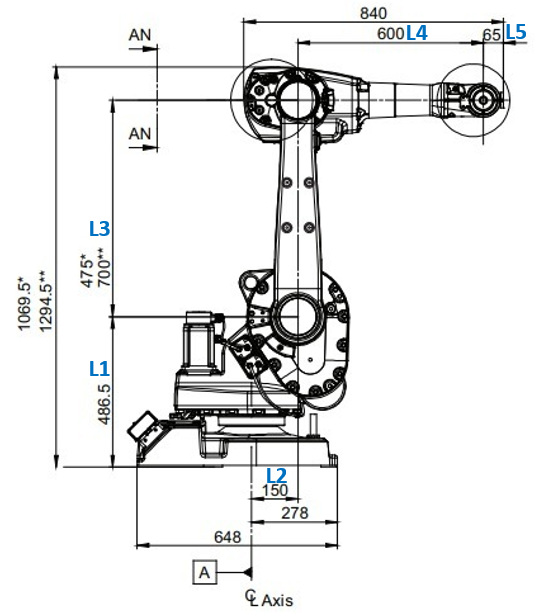

**Indica las dimensiones de la referencia IRB1600-X/1.45

  %Dimensiones del robot (escala 1:100 para optimizar la ejecucion del
  %codigo)
 L1 = 486.5/100; L2 = 150/100; L3 = 700/100; L4=600/100; L5 = 65/100; 

En la siguiente tabla se pueden obserbar las principales características de este robot:

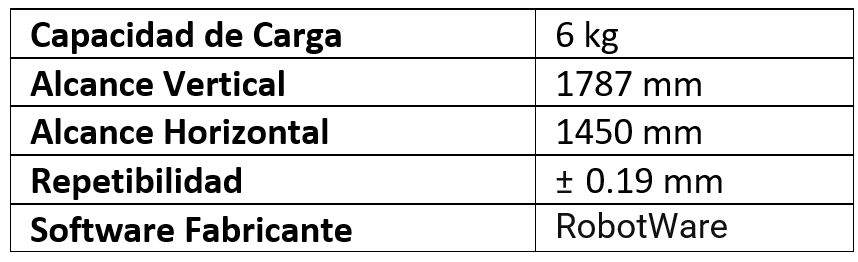

Adicionalmente, el espacio alcanzable se muestra en la siguiente figura, y en la tabla de la parte inferior se puede identificar que sus alcances horizontal y vertical son de 1450mm y 1787mm respectivamente.

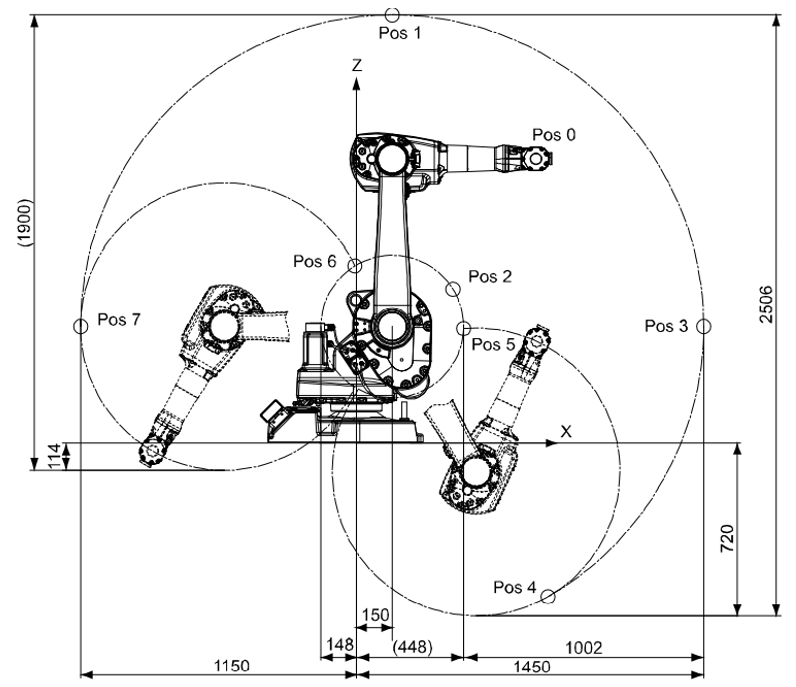 

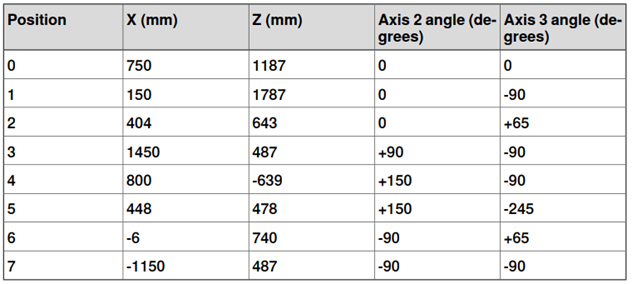

En cuanto a la calibración de el robot se realiza empleando la rutina de calibracion pendulo, esta rutina permite mover el robot a la posición cero para la calibración fina del offset de calibración del motor. Esta calibración es totalmente automática y mueve el robot a la posición leída por los sensores. Para esto, la hoja técnica del robot presenta las siguientes configuraciones:

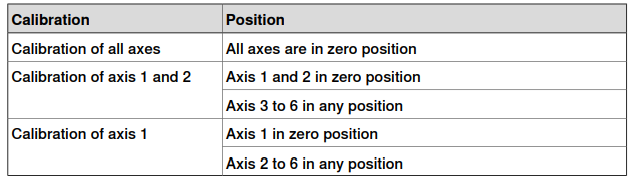

## Parte 2: Modelos.

### Modelo geometrico directo:

En esta sección se busca calcular la cinemática directa del robot ABB IRB1600 usando 3 métodos o herramientas, inicialmente se harán los cálculos manualmente y posteriormente se implementarán los modelos con ayuda del Robotics Toolbox de Peter Corke y el Robotics Syatem Toolbox. Adicionalmente, se busca crear una GUI que permita interactuar con el robot a través de variaciones en sus articulaciones y que permita visualizar su configuración.

Primero, se ubican los sistemas coordenados del robot para determinar los parametros DHmod con los que se representa el robot. En la siguiente imagen se presenta el robot con sus respectivos sistemas coordenados.

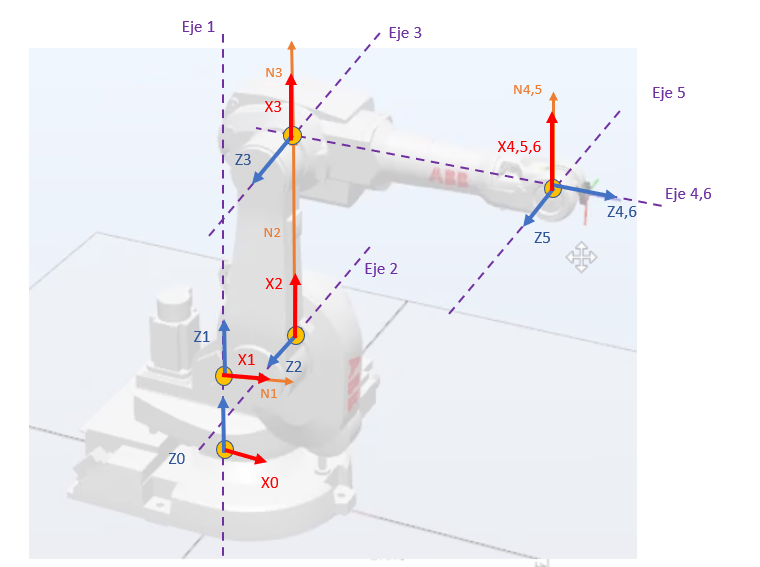

De esta manera se obtiene la siguiente tabla con los parámetros DHmod

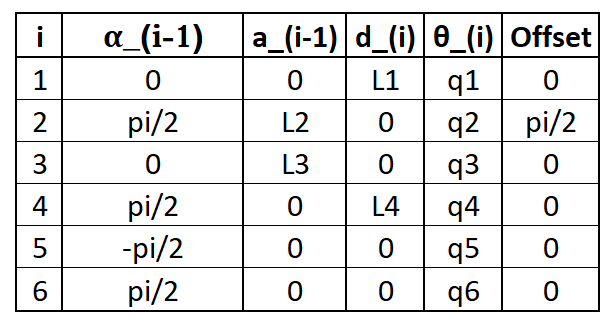

- **Método manual: **Para calcular la cinemática directa de forma manual se hallan las matrices de transformación homogénea a partir de los parámetros que se calcularon anteriormente como se muestra a continuación.


$${}^{i-1}T_i=\left\lbrack \begin{array}{cccc}
c\theta_i  & -s\theta_i  & 0\; & a_{\left\lbrace i-1\right\rbrace } \\
s\theta_i \;c\alpha_{i-1}  & c\theta_i \;\alpha_{i-1}  & -s\alpha_{i-1}  & {s\alpha }_{i-1\;} d_i \\
s\theta_i s\alpha_{i-1}  & c\theta_i \alpha_{i-1}  & c\alpha_{i-1}  & d_i \\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$
 

Este procedimiento se realizó la siguiente función, donde los parametros se encuentran dentro de la función y el unico valor de entrada es i para obtener la MTH de* i* respecto a* i-1*. 

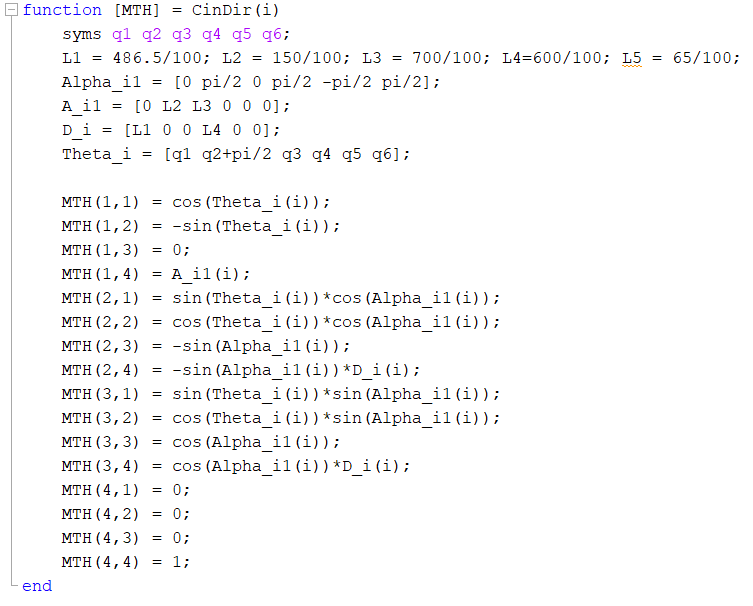

Ahora, se calculan las matrices ${}^0T_1,{}^1T_2,{}^2T_3,{}^3T_4,{}^4T_5,{}^5T_6$ y tool para obtener la matriz que describe la posición del efector final respecto a la base ${}^0T_t$. 

 % Cálculo de las MTH
MTH_01 = CinDir(1);
MTH_12 = CinDir(2);
MTH_23 = CinDir(3);
MTH_34 = CinDir(4);
MTH_45 = CinDir(5);
MTH_56 = CinDir(6);
tool = [  -1  0   0  0;...   
         0  -1   0  0 ;...
         0  0   1  L5 ;...
         0  0   0  1  ];
     
threshold = 1e-10;
%MTH del efector final respecto a la base
MTH_0t =  vpa(mapSymType(MTH_01*MTH_12*MTH_23*MTH_34*MTH_45*MTH_56*tool ,'rational', @(x) piecewise(abs(x)<=threshold, 0, x)));

Posteriormente se evaluan las posiciones de las articulaciones dadas para determinar la matriz de rotación con valores númericos. Esta matriz se iguala a la matriz de rotación de ángulos fijos que se muestra a continuación 

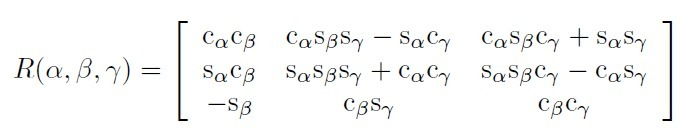

De esto se obtiene que los ángulos Roll ($\alpha$), Pitch ($\beta$) y Yaw ($\gamma$) estan dados por

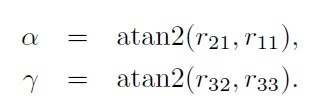

q1=0.5; q2=0.2; q3=0.4; q4=0.5; q5=0; q6=1.5;  %Valores de prueba
R_0t = eval(MTH_0t(1:3,1:3)); %Matriz de rotación con valores numéricos
%Cálculo de Angulos fijos Roll Pitch Yaw
p = atan2(-(R_0t(3,1)),sqrt((R_0t(1,1))^2+(R_0t(2,1))^2))

p = -0.3506

r = atan2(R_0t(2,1)/cos(p),R_0t(1,1)/cos(p))

r = 2.3237

y = atan2(R_0t(3,2)/cos(p),R_0t(3,3)/cos(p))

y = 0.9258

pos =  eval(MTH_0t(1:3,4)') % Vector de traslación

pos =     4.9125    2.6837   15.4803



q1=-pi/2; q2=0.3; q3=0; q4=pi/2; q5=0.4; q6=1.2; %Valores de prueba
R_0t = eval(MTH_0t(1:3,1:3)); %Matriz de rotación con valores numéricos
%Cálculo de Angulos fijos Roll Pitch Yaw
p = atan2(-(R_0t(3,1)),sqrt((R_0t(1,1))^2+(R_0t(2,1))^2))

p = -1.2002

r = atan2(R_0t(2,1)/cos(p),R_0t(1,1)/cos(p))

r = 0.3988

y = atan2(R_0t(3,2)/cos(p),R_0t(3,3)/cos(p))

y = 0.7204

pos =  eval(MTH_0t(1:3,4)') % Vector de traslación

pos =    -0.2531   -5.7353   13.5024


q1=0; q2=1; q3=-0.5; q4=2; q5=1; q6=0.5;  %Valores de prueba
R_0t = eval(MTH_0t(1:3,1:3)); %Matriz de rotación con valores numéricos
%Cálculo de Angulos fijos Roll Pitch Yaw
p = atan2(-(R_0t(3,1)),sqrt((R_0t(1,1))^2+(R_0t(2,1))^2))

p = -1.1427

r = atan2(R_0t(2,1)/cos(p),R_0t(1,1)/cos(p))

r = 0.5920

y = atan2(R_0t(3,2)/cos(p),R_0t(3,3)/cos(p))

y = 1.6874

pos =  eval(MTH_0t(1:3,4)') % Vector de traslación

pos =     1.2925   -0.4973   11.4923


q1=-1; q2=-0.3; q3=-pi/5; q4=0.4; q5=0.2; q6=1; %Valores de prueba
R_0t = eval(MTH_0t(1:3,1:3)); %Matriz de rotación con valores numéricos
%Cálculo de Angulos fijos Roll Pitch Yaw
p = atan2(-(R_0t(3,1)),sqrt((R_0t(1,1))^2+(R_0t(2,1))^2))

p = 0.1829

r = atan2(R_0t(2,1)/cos(p),R_0t(1,1)/cos(p))

r = 0.6357

y = atan2(R_0t(3,2)/cos(p),R_0t(3,3)/cos(p))

y = 2.3274

pos =  eval(MTH_0t(1:3,4)') % Vector de traslación

pos =     4.0859   -6.4566    6.3099


Por lo tanto se obtiene como resultado la siguiente tabla, es importante tener en cuenta que las dimesiones del robot fueron escaladas para facilitar la ejecucion del codigo, por lo tanto los resultados de posición deben escalarse.

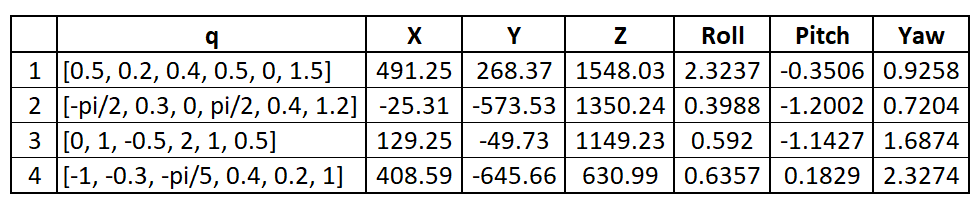

- **Usando Robotics Toolbox de Peter Corke: **Con los parámetros DHmod creamos el robot con ayuda de las funciones de este toolbox.

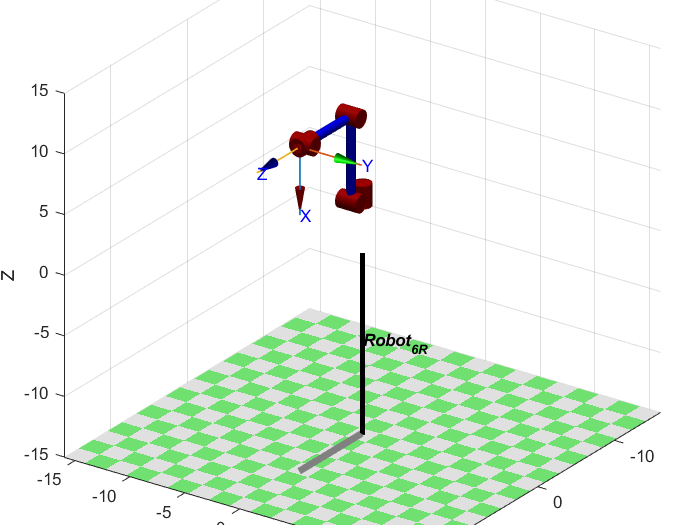

% Robot 6R
ws =  1.5* [-10 10 -10 10 -10 10];      % Espacio de trabajo
plot_options = {'workspace',ws,'scale',.5,'view',[125 25], 'tilesize',2,  'ortho',...
                'lightpos',[2 2 10] };

% Eslabones y articulaciones
%            Theta  d   a   alpha  type mdh offset  qlim
L(1) = Link('revolute', 'alpha', 0, 'a', 0, 'd', L1, 'offset', 0, 'qlim', [-pi pi], 'modified');
L(2) = Link('revolute', 'alpha', pi/2, 'a', L2, 'd', 0, 'offset', pi/2, 'qlim', [-pi/2 deg2rad(120)], 'modified');
L(3) = Link('revolute', 'alpha', 0, 'a', L3, 'd', 0, 'offset', 0, 'qlim', [deg2rad(-245) deg2rad(65)], 'modified');
L(4) = Link('revolute', 'alpha', pi/2, 'a', 0, 'd', L4, 'offset', 0, 'qlim', [deg2rad(-200) deg2rad(200)], 'modified');
L(5) = Link('revolute', 'alpha', -pi/2, 'a', 0, 'd', 0, 'offset', 0, 'qlim', [deg2rad(-115) deg2rad(115)], 'modified');
L(6) = Link('revolute', 'alpha', pi/2, 'a', 0, 'd', 0, 'offset', 0, 'qlim', [deg2rad(-400) deg2rad(400)], 'modified');

% Representación del robot     
Robot = SerialLink(L,'name', 'Robot_{6R}', 'plotopt', plot_options);
Robot.tool = [  -1  0   0  0;...     % Nuevo valor TCP
                 0  -1   0  0 ;...
                 0  0   1  L5 ;...
                 0  0   0  1  ];

% Representación del robot
q = [0 0 0 0 0 0];
Robot.plot(q)  % Dibujar el robot

Ahora, se usa la función fkine que nos permite obtener la matriz que describe la posicion y orientación del TCP respecto a la base. Finalmente se obtienen los ángulos fijos y el vector de posición

%Valores de pruba
q = [0.5 0.2 0.4 0.5 0 1.5];   
TCP = Robot.fkine(q);
tr2rpy(TCP,'zyx')

ans =     2.3237   -0.3506    0.9258


transl(TCP)

ans =     4.9125
    2.6837
   15.4803


q = [-pi/2 0.3 0 pi/2 0.4 1.2];
TCP = Robot.fkine(q);
tr2rpy(TCP,'zyx')

ans =     0.3988   -1.2002    0.7204


transl(TCP)

ans =    -0.2531
   -5.7353
   13.5024


q = [0 1 -0.5 2 1 0.5];
TCP = Robot.fkine(q);
tr2rpy(TCP,'zyx')

ans =     0.5920   -1.1427    1.6874


transl(TCP)

ans =     1.2925
   -0.4973
   11.4923


q = [-1 -0.3 -pi/5 0.4 0.2 1];
TCP = Robot.fkine(q);
tr2rpy(TCP,'zyx')

ans =     0.6357    0.1829    2.3274


transl(TCP)

ans =     4.0859
   -6.4566
    6.3099


Finalmente se obtiene la siguiente tabla con los resultados, podemos ver que los valores coinciden con los del método manual.

- **Usando Robotics System Toolbox: **En este caso se cronstruye el robot creando cada uno de sus eslabones y juntas, e indicando la posición y orientacion de cada uno de los sistemas coordenados.

body1 = rigidBody('body1');
jnt1 = rigidBodyJoint('jnt1','revolute');  
tform = trvec2tform([0, 0, L1]); % User defined 
setFixedTransform(jnt1,tform); 
body1.Joint = jnt1; 
robot = rigidBodyTree;
addBody(robot,body1,'base')
body2 = rigidBody('body2'); 
jnt2 = rigidBodyJoint('jnt2','revolute'); 
tform2 = trvec2tform([L2, 0, 0])*eul2tform([pi/2, -pi/2, 0]); % User defined 
setFixedTransform(jnt2,tform2); 
body2.Joint = jnt2; 
addBody(robot,body2,'body1'); % Add body2 to body1
body3 = rigidBody('body3'); 
body4 = rigidBody('body4'); 
jnt3 = rigidBodyJoint('jnt3','revolute'); 
jnt4 = rigidBodyJoint('jnt4','revolute'); 
tform3 = trvec2tform([L3, 0, 0]); % User defined 
tform4 = trvec2tform([0, -L4, 0])*eul2tform([0, 0, pi/2]); % User defined 
setFixedTransform(jnt3,tform3); 
setFixedTransform(jnt4,tform4); 
body3.Joint = jnt3;
body4.Joint = jnt4;
addBody(robot,body3,'body2'); % Add body3 to body2 
addBody(robot,body4,'body3'); % Add body4 to body3
body5 = rigidBody('body5'); 
body6 = rigidBody('body6'); 
jnt5 = rigidBodyJoint('jnt5','revolute'); 
jnt6 = rigidBodyJoint('jnt6','revolute'); 
tform5 = eul2tform([0, 0, -pi/2]); % User defined 
tform6 = eul2tform([0, 0, pi/2]); % User defined 
setFixedTransform(jnt5,tform5); 
setFixedTransform(jnt6,tform6);  
body5.Joint = jnt5;
body6.Joint = jnt6;
addBody(robot,body5,'body4'); % Add body5 to body4 
addBody(robot,body6,'body5'); % Add body6 to body5
bodyEndEffector = rigidBody('endeffector'); 
tform7 = trvec2tform([0, 0, L5])*eul2tform([pi, 0, 0]); % User defined 
setFixedTransform(bodyEndEffector.Joint,tform7); 
addBody(robot,bodyEndEffector,'body6');

show(robot) %Grafica el robot

ans =   Axes (Primary) with properties:

             XLim: [-16 16]
             YLim: [-16 16]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


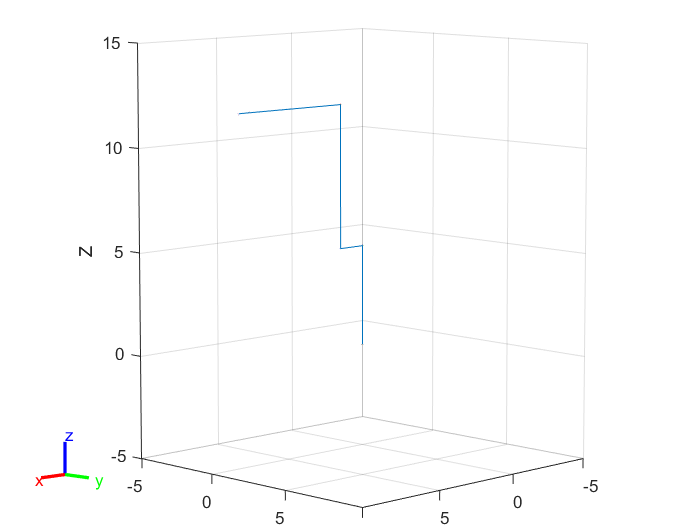

axis( [-5 10 -5 10 -5 15]); 

showdetails(robot); %Muestra las partes y detalles del robot creado

--------------------
Robot: (7 bodies)

 Idx          Body Name             Joint Name             Joint Type          Parent Name(Idx)   Children Name(s)
 ---          ---------             ----------             ----------          ----------------   ----------------
   1              body1                   jnt1               revolute                   base(0)   body2(2)  
   2              body2                   jnt2               revolute                  body1(1)   body3(3)  
   3              body3                   jnt3               revolute                  body2(2)   body4(4)  
   4              body4                   jnt4               revolute                  body3(3)   body5(5)  
   5              body5                   jnt5               revolute                  body4(4)   body6(6)  
   6              body6                   jnt6               revolute                  body5(5)   endeffector(7)  
   7        endeffector        endeffector_jnt                  fixed 

Ahora, se crea una estructura para asignar los valores a cada una de las articulaciones y se determinan los ángulos fijos y el vector de posición que describen la ubicación del efector final respecto a la base.

JointName = {'jnt1' 'jnt2' 'jnt3' 'jnt4' 'jnt5' 'jnt6'}; 
JointPosition = {0.5 0.2 0.4 0.5 0 1.5};
config=struct('JointName',JointName,'JointPosition',JointPosition);
tform = getTransform(robot,config,'endeffector','base'); %MTH
tform2trvec(tform) %Vector de traslacion 

ans =     4.9125    2.6837   15.4803


tform2eul(tform) %Euler ZYX = Angulos fijos 

ans =     2.3237   -0.3506    0.9258



JointPosition = {-pi/2 0.3 0 pi/2 0.4 1.2};
config=struct('JointName',JointName,'JointPosition',JointPosition);
tform = getTransform(robot,config,'endeffector','base'); %MTH
tform2trvec(tform) %Vector de traslacion 

ans =    -0.2531   -5.7353   13.5024


tform2eul(tform) %Euler ZYX = Angulos fijos 

ans =     0.3988   -1.2002    0.7204


JointPosition = {0 1 -0.5 2 1 0.5};
config=struct('JointName',JointName,'JointPosition',JointPosition);
tform = getTransform(robot,config,'endeffector','base'); %MTH
tform2trvec(tform) %Vector de traslacion 

ans =     1.2925   -0.4973   11.4923


tform2eul(tform) %Euler ZYX = Angulos fijos 

ans =     0.5920   -1.1427    1.6874


JointPosition = {-1 -0.3 -pi/5 0.4 0.2 1};
config=struct('JointName',JointName,'JointPosition',JointPosition);
tform = getTransform(robot,config,'endeffector','base'); %MTH
tform2trvec(tform) %Vector de traslacion 

ans =     4.0859   -6.4566    6.3099


tform2eul(tform) %Euler ZYX = Angulos fijos 

ans =     0.6357    0.1829    2.3274


Nuevamente se obtiene la misma tabla de resutados que en los dos casos anteriores, lo que corrobora el funcionamiento de estos métodos y herramientas.

- **GUI: **Usando el Robotics Systeems Toolbox se desarrolló una interfaz que permita al usuario interactuar con el robot modificando el valor de sus articulaciones y viendo estos cambios en su configuración y en la posición y orientación del efector final.

La siguiente imagen presenta las partes de la interfaz:

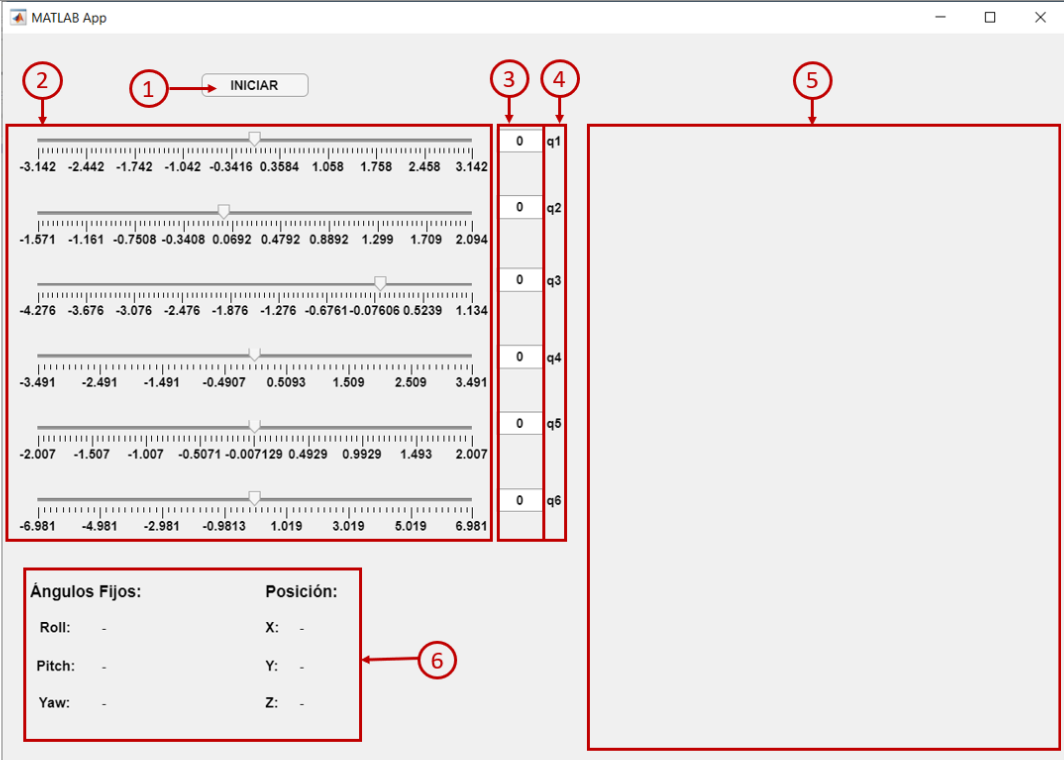

Donde los numerales de la imagen corresponden a las siguientes funciones:

- Botón de inicio: Este botón se debe presionar al ejecutar la GUI, al hacerlo se cargan la imagen del robot en el espacio de la izquierda y los valores de la ubicación del TCP en los espacios de Angulos fijos y posición.

- Sliders: Esta herramienta permite cambiar el valor de las articulaciones deslizandose sobre la regleta. Como se observa en la imagen, los valores que se pueden seleccionar se encuentran en radianes y estan limitados dentro del rango de alcance de cada articulación.

- Recuadros de texto: En estos espacios es posible ingresar el valor exacto de las articulaciones más facilmente que con los sliders. En este caso también se limitó el ingreso de valores con el rango de alcance de cada articulación. En caso de ingresar un valor fuera de este rango se mostrará el mensaje "Value must be between" y el rango de la articulación correspondiente.

- Indicadores de articulación: Estas etiquetas indican el numero de la articulación que se modifica en la fila que se encuentran ubicados.

- Gráfica: En este espacio se cargará la imagen del robot una vez se presione el botón de inicio. Esta imagen se actualizará cuando se realice algún cambio en los espacios 2 o 3.

- Cinemática directa: En esta sección se presenta la posición y orientación del efector final que se calcula haciendo uso de las funciones del toolbox. Esta sección, al igual que la imagen se actualizará cuando se realice algun cambio en los espacios 2 o 3.

Una vez implementada la GUI se realizaron las pruebas correspondientes a los valores de la tabla para verificar su funcionamiento y se obtuvieron los siguientes resultados:

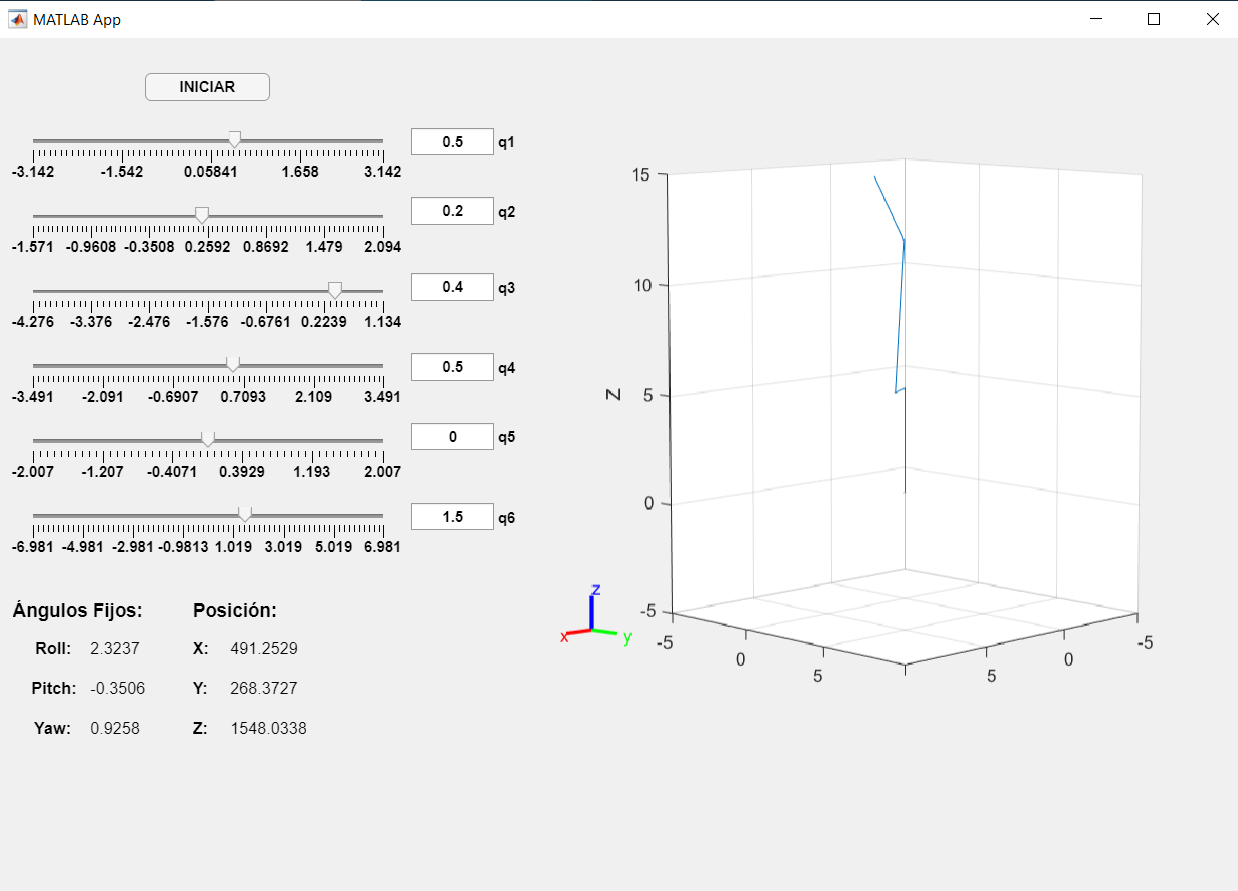    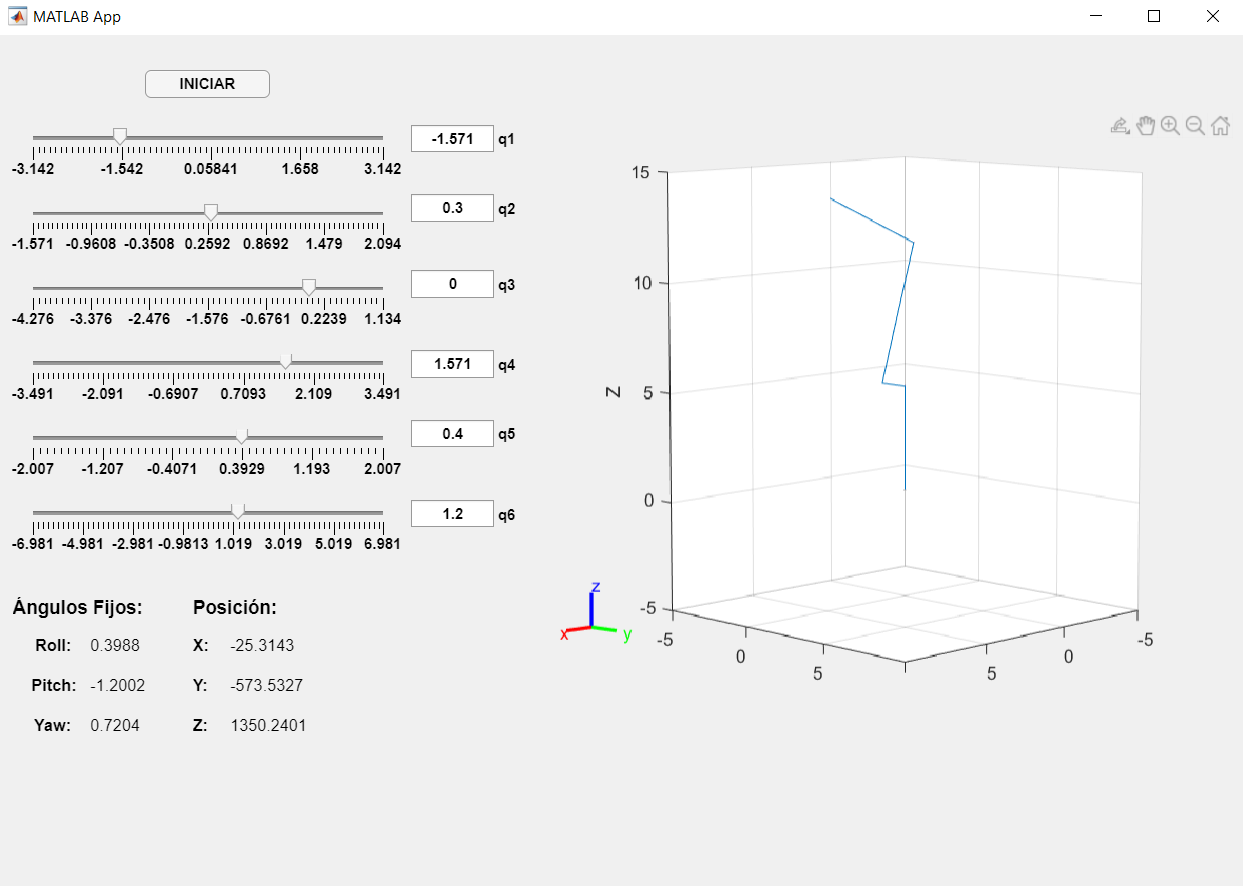

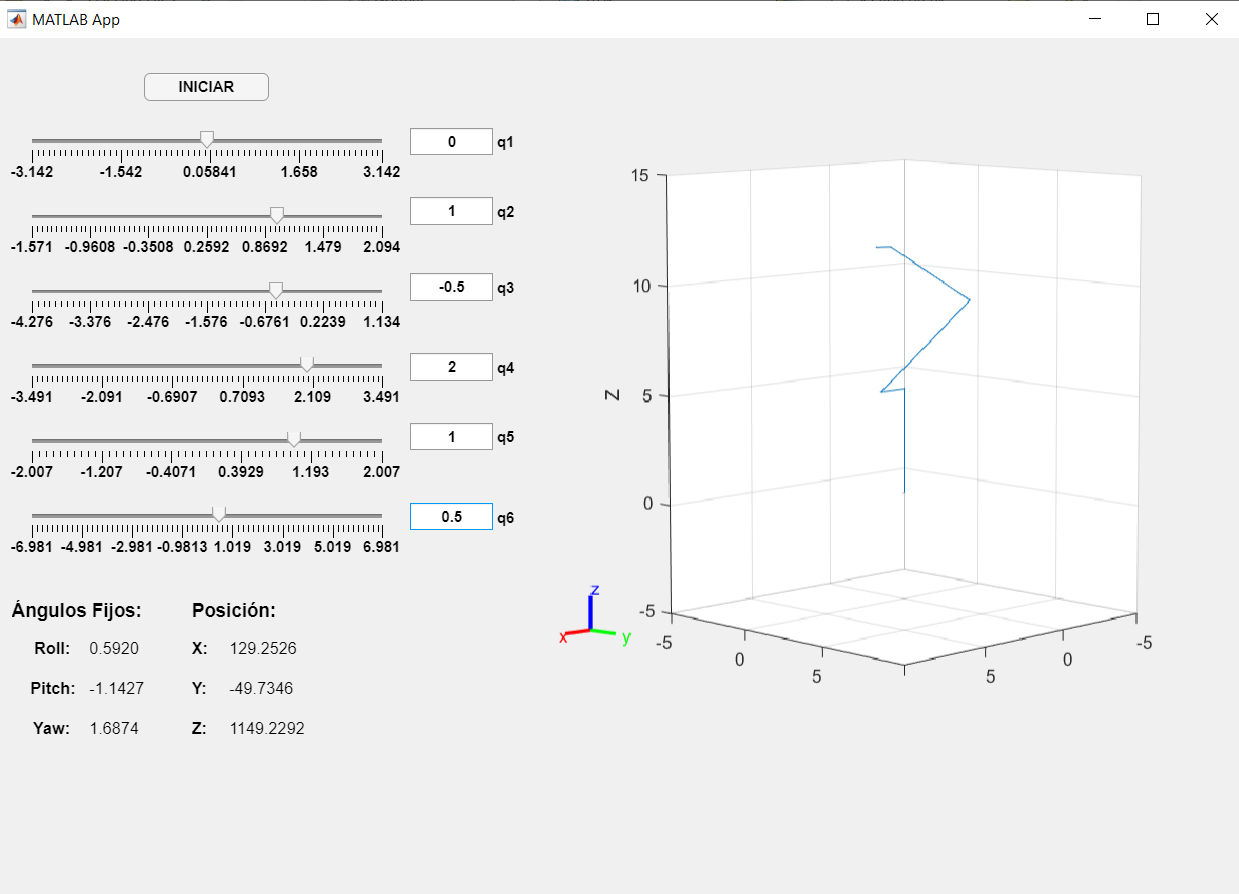    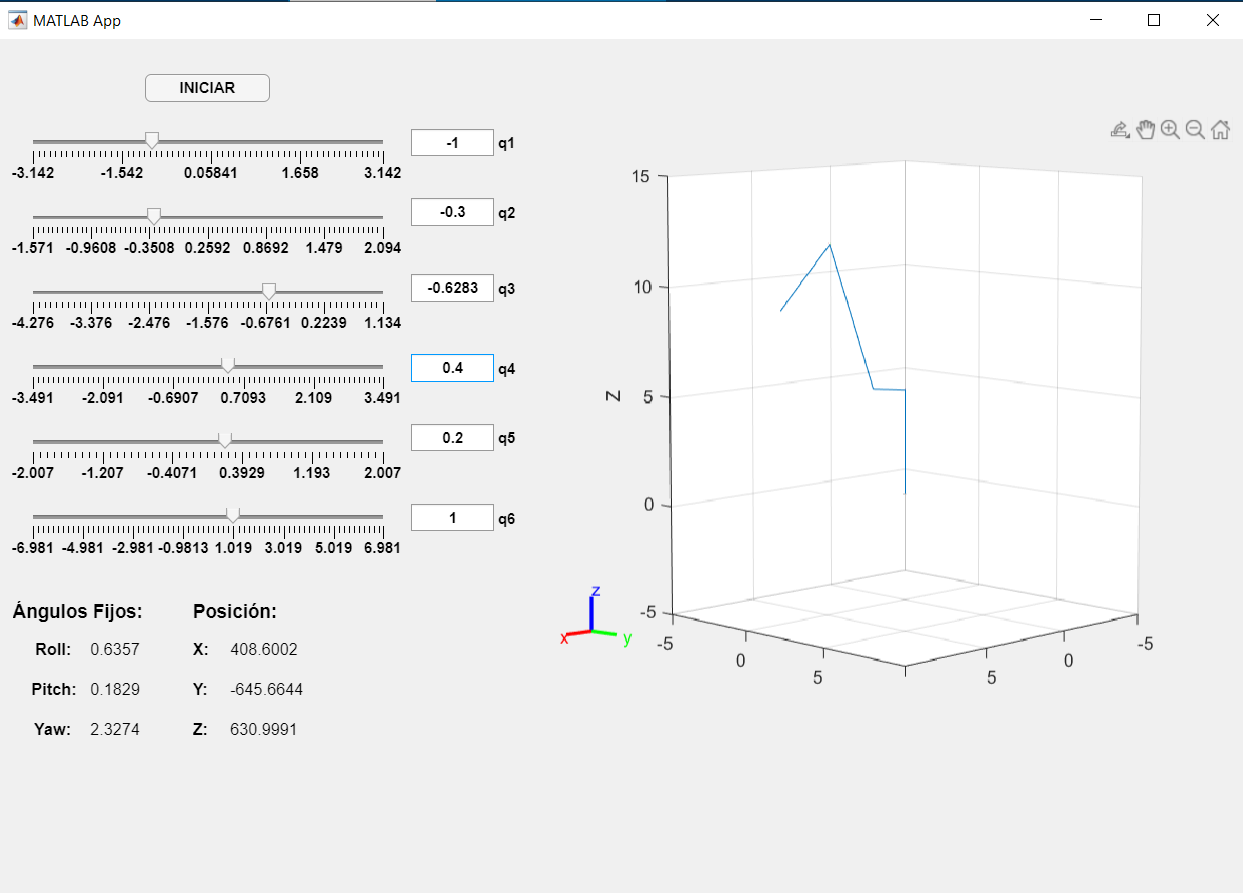

Al contrastar los resultados con los obtenidos en la implementación de los toolbox corroboramos que la GUI funciona correctamente